# Schwarz Alternating Algorithm - Eigenvalue Problem

In this example, we are going to build the Eigenvalue Problem for a rectangular membrane. Then, we are going to use the Schwarz Alternating Algorithm to solve the same problem using smaller, intersecting domains.

Lets start by adding the path to 

cd ..
run startup.m
cd UserGuide

## Geometry Description

The geometry we are going to use is a 1m by 1.5m rectangular membrane. This can be describled by a ruled surface between two lines.

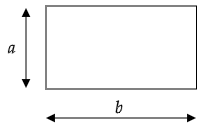

where a = 1m and b = 1.5m

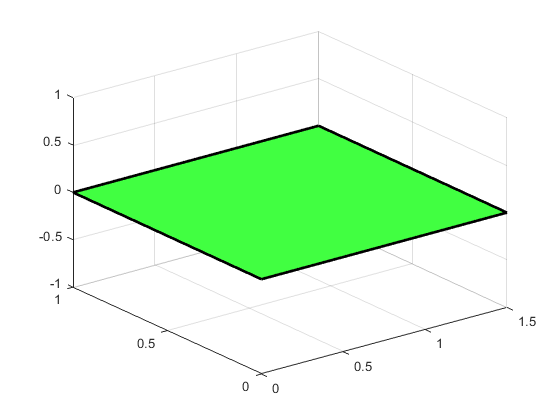

% Geometry Input
a = 1;
b = 1.5;
% Ruled Surface Definition
P1 = [0 0 0 1];
P2 = [0 a 0 1];
line1 = geo_line(P1,P2); % First line
P3 = [b 0 0 1];
P4 = [b a 0 1];
line2 = geo_line(P3,P4); % Second line
Omega = geo_ruled(line1,line2); % The Ruled Surface defined by lines 1 and 2
n = 1;
figure(n)
Omega.plot_geo('coarse',0,1)

In this problem, we will also separate the membrane in two intersecting subdomains. What we will use as a measure of the intersection is the percentage of the intersection in regards to the total area of the membrane. We make this as:

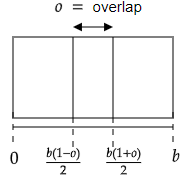

Lines 1 and 2 are still part of the object, but we need to make Lines 3 and 4, that limit the subdomains to create the ruled surfaces.

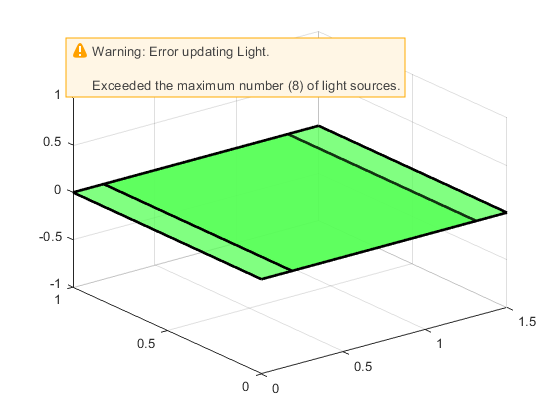

overlap = 0.75; % Percentage of intersection area
P5 = [b*(1+overlap)/2 0 0 1];
P6 = [b*(1+overlap)/2 a 0 1];
line3 = geo_line(P5,P6);
P7 = [b*(1-overlap)/2 0 0 1];
P8 = [b*(1-overlap)/2 a 0 1];
line4 = geo_line(P7,P8);

Omega1 = geo_ruled(line1,line3); % Subdomain 1
Omega2 = geo_ruled(line4,line2); % Subdomain 2
n = n+1;
figure(n)
Omega1.plot_geo('coarse',0,1)
hold on
Omega2.plot_geo('coarse',0,1)
alpha(0.2) % Make them transparent so we can see the intersection lines

## k-Refining the Models

We will p refine the curves some number of times, and then h-refine them.

p = 2; % Number of p refinements
    Omega.DegreeElevate(p,1);
    Omega.DegreeElevate(p,2);
    Omega1.DegreeElevate(p,1);
    Omega1.DegreeElevate(p,2);
    Omega2.DegreeElevate(p,1);
    Omega2.DegreeElevate(p,2);
h = 20; % Number of h-refinements
interval = linspace(0,1,h+2);
interval = setdiff(interval,[0, 1]);
    Omega.KnotRefine(interval,1);
    Omega.KnotRefine(interval,2);
    Omega1.KnotRefine(interval,1);
    Omega1.KnotRefine(interval,2);
    Omega2.KnotRefine(interval,1);
    Omega2.KnotRefine(interval,2);

## Assembly

    [K, M, ID] = MembraneAssemble(Omega);
    [K1,M1,ID1] = MembraneAssemble(Omega1);
    [K2,M2,ID2] = MembraneAssemble(Omega2);

## Zero-Displacement Constraints

For this eigenvalue problem, we have that the whole boundary has zero displacement. To apply this boundary condition to an eigenvalue problem, we have to solve the eigenvalue problem without the constrained DOFs and then add then as zero values in the autovector arrays, much like a Dirichlet Boundary Condition.

Since this processing is done much like a Dirichlet Boundary Condition, we can use the GetBoundaryConditionArray function.

We have named the four boundaries of Omega and Omega1,2 as:

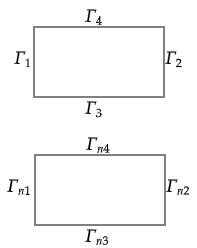

We have to be aware that, in this parametrization of the membrane, y moves along with the first parametric direction and x moves along with the second:

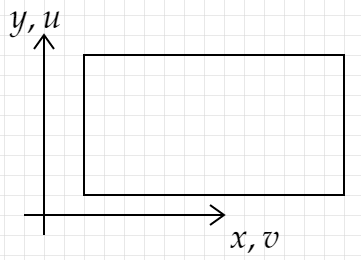

Remembering the syntax:

    % Omega
    Gamma1 = GetBoundaryConditionArray(Omega,2,0,0);
    Gamma2 = GetBoundaryConditionArray(Omega,2,1,0);
    Gamma3 = GetBoundaryConditionArray(Omega,1,0,0);
    Gamma4 = GetBoundaryConditionArray(Omega,1,1,0);
  
    % Omega 1
    Gamma11 = GetBoundaryConditionArray(Omega1,2,0,0);
    Gamma12 = GetBoundaryConditionArray(Omega1,2,1,0);
    Gamma13 = GetBoundaryConditionArray(Omega1,1,0,0);
    Gamma14 = GetBoundaryConditionArray(Omega1,1,1,0);
    % Omega 2
    Gamma21 = GetBoundaryConditionArray(Omega2,2,0,0);
    Gamma22 = GetBoundaryConditionArray(Omega2,2,1,0);
    Gamma23 = GetBoundaryConditionArray(Omega2,1,0,0);
    Gamma24 = GetBoundaryConditionArray(Omega2,1,1,0);

Remember that the GetBoundaryConditionArray return a 2 column vector, with lift information as well. We wont need it to enforce the BCs. Let's add all the Boundary Information in a single column vector:

     ConstrainedOmega = unique([Gamma1(:,1); Gamma2(:,1); Gamma3(:,1); Gamma4(:,1)]);
     ConstrainedOmega1 = unique([Gamma11(:,1); Gamma13(:,1); Gamma14(:,1)]);
     ConstrainedOmega2 = unique([Gamma22(:,1); Gamma23(:,1); Gamma24(:,1)]);

It's important to remove the repeating DOFs, hence why we use the unique() command.

Now, removing the DOFs from the Stiffness and Mass matrices, and storing the old ones:

KK = K; KK1 = K1; KK2 = K2; MM = M; MM1 = M1; MM2 = M2;
% Omega
K(ConstrainedOmega,:) = [];
K(:,ConstrainedOmega) = [];
M(ConstrainedOmega,:) = [];
M(:,ConstrainedOmega) = [];

% Omega 1
K1(ConstrainedOmega1,:) = [];
K1(:,ConstrainedOmega1) = [];
M1(ConstrainedOmega1,:) = [];
M1(:,ConstrainedOmega1) = [];

% Omega 2
K2(ConstrainedOmega2,:) = [];
K2(:,ConstrainedOmega2) = [];
M2(ConstrainedOmega2,:) = [];
M2(:,ConstrainedOmega2) = [];

Now we solve the Eigen Value problem, for the first eigenvalue only. As a reminder: since matrix operations in matlab are not very efficient in sparse form, but the Eigs solve is, all matrices given by IRACEMA are given in full(). We have to converse then to sparse() before using the eigs or \ commands.

% Omega
K = sparse(K);
M = sparse(M);
[EigenVec, EigenVal] = eigs(K,M,1,'sm');

% Omega 1
K1 = sparse(K1);
M1 = sparse(M1);
[EigenVec1, EigenVal1] = eigs(K1,M1,1,'sm');

% Omega 2
K2 = sparse(K2);
M2 = sparse(M2);
[EigenVec2, EigenVal2] = eigs(K2,M2,1,'sm');

To correctly visualize the Models, we must add back the zero valued constrined DOFs to the autovector. We do this by a function called BoundariesPostProcess:

EigenVec = BoundariesPostProcess(EigenVec,ConstrainedOmega);
EigenVec1 = BoundariesPostProcess(EigenVec1,ConstrainedOmega1);
EigenVec2 = BoundariesPostProcess(EigenVec2,ConstrainedOmega2);

## Preliminary Results and Visualization

We then construct the new geometries for visualization using the VisualizeModes function:

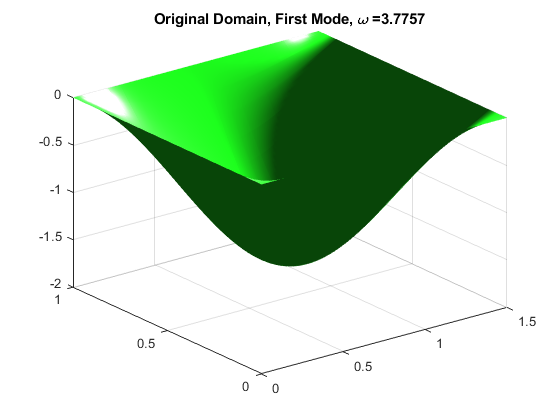

OmegaModes = VisualizeModes(Omega,EigenVec,ID);
Omega1Modes = VisualizeModes(Omega1,EigenVec1,ID1);
Omega2Modes = VisualizeModes(Omega2,EigenVec2,ID2);
n = n+1;
figure(n)
OmegaModes{1}.plot_geo;
title(strcat('Original Domain, First Mode, \omega = ',num2str(sqrt(EigenVal))))
xlim([0 1.5])

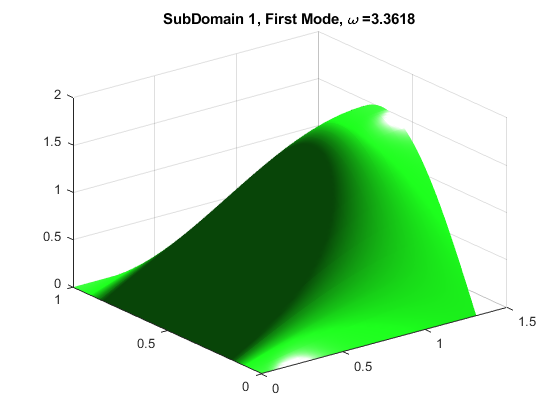

n = n+1;
figure(n)
Omega1Modes{1}.plot_geo;
title(strcat('SubDomain 1, First Mode, \omega = ',num2str(sqrt(EigenVal1))))
xlim([0 1.5])

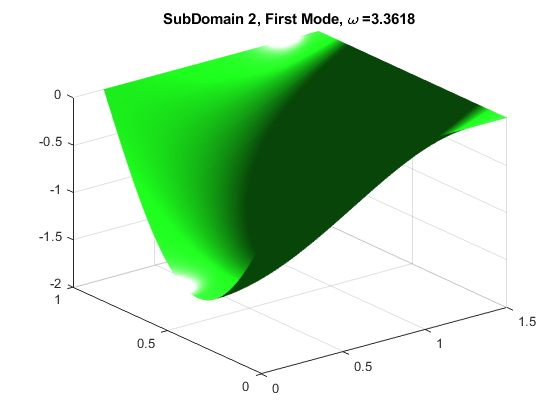

n = n+1;
figure(n)
Omega2Modes{1}.plot_geo;
title(strcat('SubDomain 2, First Mode, \omega = ',num2str(sqrt(EigenVal2))))
xlim([0 1.5])

Sometimes, when evaluating Eigenvalues, given the same solver for the same problem, we can have the same eigenvector multiplied by -1. Later, we will update the stiffness matrices in regards to the solution of the eigenvalue problem, so it's problematic for then to have different values. We will, then, normalize the eigenvalues so they are always pointing in the same direction and having maximum deformation of 1.

if abs(min(EigenVec)) > abs(max(EigenVec)) % If the absolute of the minimum value is higher than of the maximum, flip the values
    EigenVec = -EigenVec;
end
if abs(min(EigenVec1)) > abs(max(EigenVec1))
    EigenVec1 = -EigenVec1;
end
if abs(min(EigenVec2)) > abs(max(EigenVec2))
    EigenVec2 = -EigenVec2;
end

% Normalizing
EigenVec = EigenVec/max(EigenVec); 
EigenVec1 = EigenVec1/max(EigenVec1);
EigenVec2 = EigenVec2/max(EigenVec2);

Now we repeat the plotting, this time, compressed into one subplot:

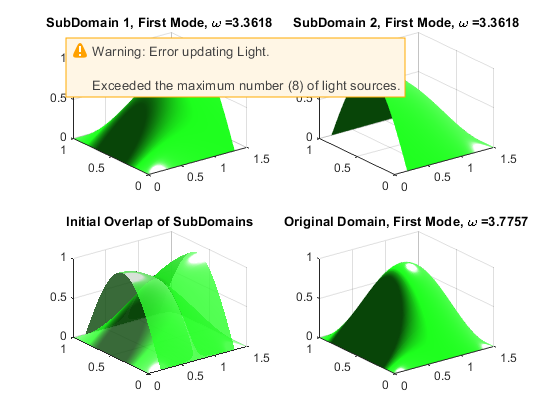

OmegaModes = VisualizeModes(Omega,EigenVec,ID); % Update the Model with new EigenVec values
Omega1Modes = VisualizeModes(Omega1,EigenVec1,ID1);
Omega2Modes = VisualizeModes(Omega2,EigenVec2,ID2);
n = n+1;
figure(n)
subplot(2,2,1)
Omega1Modes{1}.plot_geo;
title(strcat('SubDomain 1, First Mode, \omega = ',num2str(sqrt(EigenVal1))))
xlim([0 1.5])

subplot(2,2,2)
Omega2Modes{1}.plot_geo;
title(strcat('SubDomain 2, First Mode, \omega = ',num2str(sqrt(EigenVal2))))
xlim([0 1.5])

subplot(2,2,3)
Omega1Modes{1}.plot_geo;
hold on
Omega2Modes{1}.plot_geo;
title(strcat('Initial Overlap of SubDomains'))
xlim([0 1.5])
alpha(0.8);

subplot(2,2,4)
OmegaModes{1}.plot_geo;
title(strcat('Original Domain, First Mode, \omega = ',num2str(sqrt(EigenVal))))
xlim([0 1.5])

With this initial solution to the problem, now we start the Schwarz Alternating Algorithm

## Schwarz Alternating Algorithm for EigenValue Problems

For the Schwarz Algorithm, we wish to update the values on the free boundary of a subdomain using the values of the function of the other subdomain. However, this can't be done in Eigenvalue Problems, since the only possible Dirichlet boundary condition available for these kind of problems are 0.

This is remedied by using a special Robin Boundary Condition, that we call Lui Boundary Condition, following the publication of this work by Lui*. The conditions at the boundary of the subdomains are evaluated as:

*S. H. Lui, Domain decomposition methods for eigenvalue problems, Journal of Computational and Applied Mathematics 117 (2000)


$$u_2^{(i)} \frac{\partial u_1^{(i+1)}}{\partial n_1}  - \frac{\partial u_2^{(i)}}{\partial n_1} u_1^{(i+1)} = 0 \quad \text{on } \Gamma _1$$


and


$$u_1^{(i)} \frac{\partial u_2^{(i)}}{\partial n_2}  - u_2^{(i)}\frac{\partial u_1^{(i)}}{\partial n_2} = 0 \quad \text{on } \Gamma _2$$


We can manipulate these expressions to resemble the general form of the Robin Boundary Condition:


$$\nabla u \cdot \textbf{n} = r - \beta u \quad \text{on } \Gamma$$


as:


$$\nabla u_1^{(i+1)} \cdot \textbf{n}_1 = \left(\frac{1}{u_2^{(i)}} \nabla u_2 ^{(i)} \cdot \textbf{n}_1 \right) u_1^{(i+1)} \quad \text{on } \Gamma_1$$


and


$$\nabla u_2^{(i)} \cdot \textbf{n}_2 = \left(\frac{1}{u_1^{(i)}} \nabla u_1 ^{(i)} \cdot \textbf{n}_2 \right) u_2^{(i)} \quad \text{on } \Gamma_2$$


We have that $r = 0$ for both conditions, and that:

$\beta = \left(\frac{1}{u_2^{(i)}} \nabla u_2 ^{(i)} \cdot \textbf{n}_1 \right)$ on $\Gamma_1$ and

$\beta = \left(\frac{1}{u_1^{(i)}} \nabla u_1 ^{(i)} \cdot \textbf{n}_2 \right)$ on $\Gamma_2$.

This works for most values of $u_1$ and $u_2$, however, when they approach zero, numerical instabilities occur. We will make an intervening if for this case and arbitrate Beta to be a penalty value. This works because, by adding a very high value to the stiffness of the mentioned DOF, the solution will approach zero.

Also, one has to observe that each time we iterate on the Schwarz Algorithm, we need to exchange information between subdomains. On $\Gamma_1$ we require the knowledge of $u_2$ and $\nabla u_2$, and on $\Gamma_2$, we require information of $u_1$ and $\nabla u_1$.

On a quadrature point level, this means that, when integrating the boundary in $\Gamma _1$, for a given quadrature point in the parametric space of the subdomain $\Omega _1$, we need to know where it lies on the parametric space of the subdomain $\Omega _2$, however, the only information that we have for a fact, is that this point occupies the same physical space (x,y,z) in both subdomains.

This means that a function inverse, $f^{-1}(x,y,z) = (u,v)$ must be supplied for both subdomains so they can trade information. There's no analytical inverse function for an arbitrary NURBS curve, however, for a rectangular 2D domain with an overlapping center, we easily deduce a function inverse for both domains:

$f^{-1}(x,y) = (u,v) = \left(y, \frac{2x}{b(1+o)}\right)$ in $\Omega_1$ and

$f^{-1}(x,y) = (u,v) = \left( y, \left( x - \frac{b(1-o)}{2} \right) \frac{1}{b-\frac{b(1-o)}{2}} \right)$ in $\Omega_2$.

So lets build the inverse functions and check their results:

InvOmega1 = @(x,y) [y, 2*x/(b*(1+overlap))];
tmp = b*(1-overlap)/2;
InvOmega2 = @(x,y) [y, (x - tmp)/(b - tmp)];
% Let's calculate a random point in [0,1]x[0,1]:
sample = rand(2,1);
point1 = Omega1.eval_point(sample(1),sample(2));
point2 = Omega2.eval_point(sample(1),sample(2));
display(strcat('The sampled point was (u,v) = (',num2str(sample(1),4),',',num2str(sample(2),4),')'))

The sampled point was (u,v) = (0.04617,0.09713)


display(strcat('Which corresponded to the coordinates (', num2str(point1.x,4),',',num2str(point1.y,4),') in Omega1'));

Which corresponded to the coordinates (0.1275,0.04617) in Omega1


display(strcat('and (', num2str(point2.x,4),',',num2str(point2.y,4),') in Omega_2'));

and (0.315,0.04617) in Omega_2


invpoint1 = InvOmega1(point1.x,point1.y);
invpoint2 = InvOmega2(point2.x,point2.y);
display(strcat('The Inverse Function 1 gave (u,v) = (',num2str(invpoint1(1),4),',',num2str(invpoint1(2),4),')'));

The Inverse Function 1 gave (u,v) = (0.04617,0.09713)


display(strcat('and the Inverse Function 2 gave (u,v) = (',num2str(invpoint2(1),4),',',num2str(invpoint2(2),4),')'));

and the Inverse Function 2 gave (u,v) = (0.04617,0.09713)


## First Iteration of the Algorithm

Let's start our iteration of Schwarz algorithm by applying the Lui Boundary Condition on $\Gamma_1$. For that, we need to get the elements that describe the boundary $\Gamma_{12}$. Remembering the GetBoundaryElements Function:

Gamma12 = GetBoundaryElements(Omega1,2,1,[0,0]); % We don't really care about lift values here, since we run Lui BC
Gamma21 = GetBoundaryElements(Omega2,2,0,[0,0]); % While we are at it, let's also get the elements of the boundary 21.